clear all

OG = im2double(imread('SCO700eV_processed_HS.png'));
OG_threshold = im2double(imread('SCO700_bin.png'));

randImg = im2double(imread('randSpinLatt.png'));
zerosImg = im2double(imread('zeros.png'));
onesImg = im2double(imread('ones.png'));
meanOG = im2double(imread('mean.png'));

J47 = im2double(imread('D:\IsingModel\IsingModelOLD\oldMatlab\210422_J47K_T6.3191K_1_0.7071_0.5_S83.9_squeeze6LG.png'));
J47pt5 = im2double(imread('D:\IsingModel\IsingModelOLD\oldMatlab\210421_J47.5K_T6.2526K_1_0.7071_0.5_S83.9_squeeze6LG.png'));
J48 = im2double(imread('D:\IsingModel\IsingModelOLD\oldMatlab\210421_J48K_T6.1875K_1_0.7071_0.5_S83.9_squeeze6LG.png'));
J48pt5 = im2double(imread('D:\IsingModel\IsingModelOLD\oldMatlab\210421_J48.5K_T6.1237K_1_0.7071_0.5_S83.9_squeeze6LG.png'));


## Do Cross Correlation

% OG = OG./max(max(OG));
% OG_threshold = OG_threshold./max(OG_threshold(:));
% J47 = J47./max(J47(:));
% J47pt5 = J47pt5./max(J47pt5(:));
% J48 = J48./max(J48(:));
% J48pt5 = J48pt5./max(J48pt5(:));


% OGcc = OG - mean(mean(OG));
% OGthcc = OG_threshold - mean(mean(OG_threshold));
% randIMGcc = randImg;% - mean(mean(randImg));
% J47cc = J47 - mean(mean(J47));
% J47pt5cc = J47pt5 - mean(mean(J47pt5));
% J48cc = J48 - mean(mean(J48));
% J48pt5cc = J48pt5 - mean(mean(J48pt5));


OGcc = OG;
OGthcc = OG_threshold;
randIMGcc = randImg;% - mean(mean(randImg));
J47cc = J47;
J47pt5cc = J47pt5;
J48cc = J48;
J48pt5cc = J48pt5;


cself = xcorr2(OGcc, OGcc);
cselfmax = max(cself(:))

cselfmax = 1.5696e+05


%czeros = xcorr2(OGcc, zerosImg);
%czerosmax = max(czeros(:))

cones = xcorr2(OGcc, onesImg);
conesmax = max(cones(:))/cselfmax

conesmax = 2.4720


cmean = xcorr2(OGcc, meanOG);
cmeanmax = max(cmean(:))/cselfmax

cmeanmax = 0.9015


crand = xcorr2(OGcc, randImg);
crandmax = max(crand(:))/cselfmax

crandmax = 0.8385


c47 = xcorr2(OGcc, J47cc);
c47max = max(c47(:))/cselfmax

c47max = 0.1213


c47pt5 = xcorr2(OGcc, J47pt5cc);
c47pt5max = max(c47pt5(:))/cselfmax

c47pt5max = 0.1395


c48 = xcorr2(OGcc, J48cc);
c48max = max(c48(:))/cselfmax

c48max = 0.0985


c48pt5 = xcorr2(OGcc, J48pt5cc);
c48pt5max = max(c48pt5(:))/cselfmax

c48pt5max = 0.0687

cselfth = xcorr2(OGthcc, OGthcc);
cselfthmax = max(cselfth(:))

cselfthmax = 133519


%czerosth = xcorr2(OGthcc, zerosImg);
%czerosthmax = max(czerosth(:))

conesth = xcorr2(OGthcc, onesImg);
conesthmax = max(conesth(:))/cselfthmax

conesthmax = 1


cmeanth = xcorr2(OGthcc, meanOG);
cmeanthmax = max(cmeanth(:))/cselfthmax

cmeanthmax = 0.3647


crandth = xcorr2(OGthcc, randImg);
crandthmax = max(crandth(:))/cselfthmax

crandthmax = 0.3468


c47th = xcorr2(OGthcc, J47cc);
c47thmax = max(c47th(:))/cselfthmax

c47thmax = 0.0644


c47pt5th = xcorr2(OGthcc, J47pt5cc);
c47pt5thmax = max(c47pt5th(:))/cselfthmax

c47pt5thmax = 0.0643


c48th = xcorr2(OGthcc, J48cc);
c48thmax = max(c48th(:))/cselfthmax

c48thmax = 0.0601


c48pt5th = xcorr2(OGthcc, J48pt5cc);
c48pt5thmax = max(c48pt5th(:))/cselfthmax

c48pt5thmax = 0.0537

## Bar Chart of Cross Correlation Values

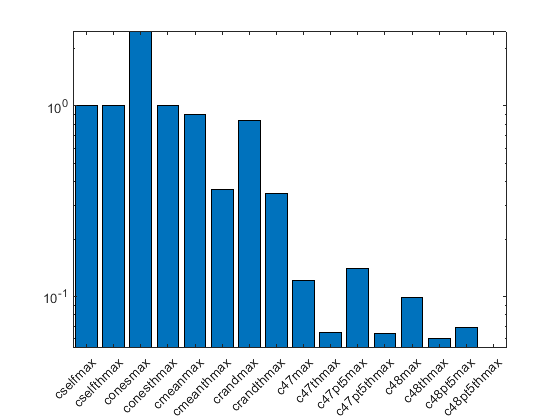

cc_names = categorical({'cselfmax', 'cselfthmax', ...
    'conesmax', 'conesthmax', 'cmeanmax', 'cmeanthmax', 'crandmax', 'crandthmax', ...
    'c47max', 'c47thmax', 'c47pt5max', 'c47pt5thmax', ...
    'c48max', 'c48thmax', 'c48pt5max', 'c48pt5thmax'});

cc_names = reordercats(cc_names,{'cselfmax', 'cselfthmax', ...
    'conesmax', 'conesthmax', 'cmeanmax', 'cmeanthmax', 'crandmax', 'crandthmax', ...
    'c47max', 'c47thmax', 'c47pt5max', 'c47pt5thmax', ...
    'c48max', 'c48thmax', 'c48pt5max', 'c48pt5thmax'});

cc_values = [1, 1, ...
    conesmax, conesthmax, cmeanmax, cmeanthmax, crandmax, crandthmax, ...
    c47max, c47thmax, c47pt5max, c47pt5thmax, ...
    c48max, c48thmax, c48pt5max, c48pt5thmax];

figure;
bar(cc_names, cc_values);
set(gca, 'YScale', 'log')

## Show cross correlations

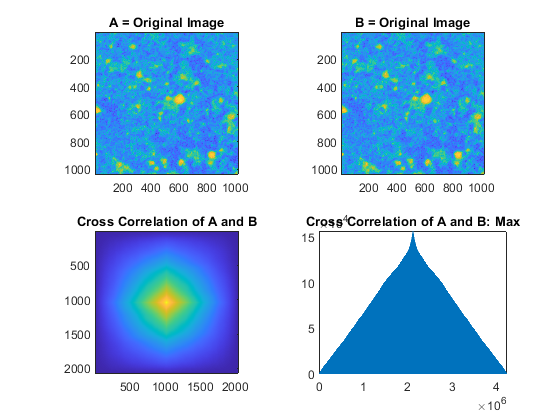

figure;
subplot(2, 2, 1)
imagesc(OG)
title('A = Original Image')
axis square

subplot(2, 2, 2)
imagesc(OG)
title('B = Original Image')
axis square

subplot(2, 2, 3)
imagesc(cself)
axis square
title('Cross Correlation of A and B')

subplot(2, 2, 4)
plot(cself(:))
title('Cross Correlation of A and B: Max')

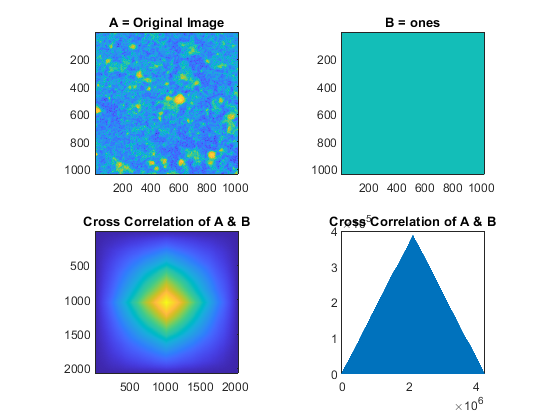

figure;
subplot(2, 2, 1)
imagesc(OG)
title('A = Original Image')
axis square

subplot(2, 2, 2)
imagesc(onesImg)
title('B = ones')
axis square

subplot(2, 2, 3)
imagesc(cones)
axis square
title('Cross Correlation of A & B')

subplot(2, 2, 4)
plot(cones(:))
title('Cross Correlation of A & B')
axis square

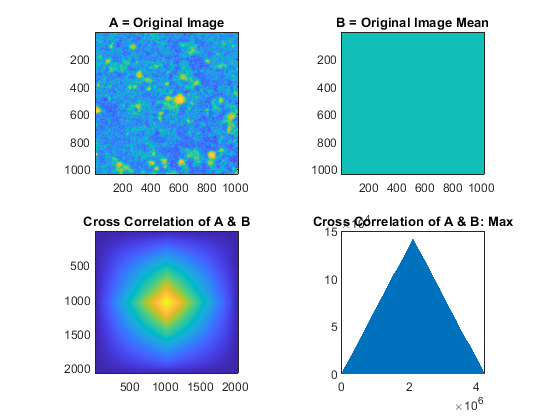

figure;
subplot(2, 2, 1)
imagesc(OG)
title('A = Original Image')
axis square

subplot(2, 2, 2)
imagesc(meanOG)
title('B = Original Image Mean')
axis square

subplot(2, 2, 3)
imagesc(cmean)
axis square
title('Cross Correlation of A & B')

subplot(2, 2, 4)
plot(cmean(:))
axis square
title('Cross Correlation of A & B: Max')

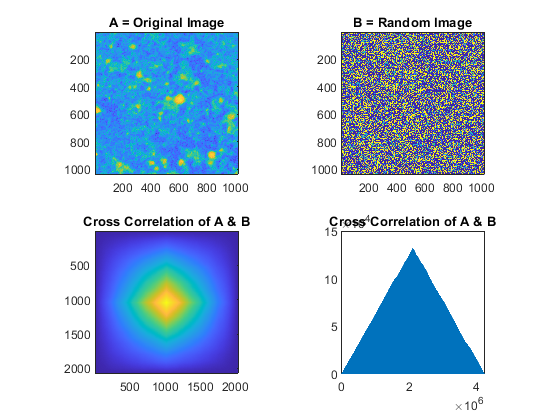

figure;

subplot(2, 2, 1)
imagesc(OG)
axis square
title('A = Original Image')

subplot(2, 2, 2)
imagesc(randImg)
axis square
title('B = Random Image')

subplot(2, 2, 3)
imagesc(crand)
axis square
title('Cross Correlation of A & B')

subplot(2, 2, 4)
plot(crand(:))
axis square
title('Cross Correlation of A & B')

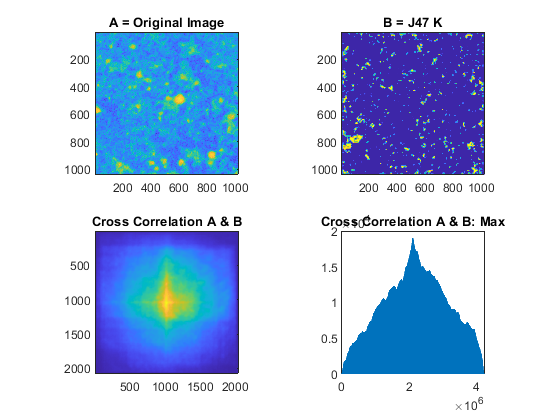

figure;

subplot(2, 2, 1)
imagesc(OG)
axis square
title('A = Original Image')

subplot(2, 2, 2)
imagesc(J47)
axis square
title('B = J47 K')

subplot(2, 2, 3)
imagesc(c47)
axis square
title('Cross Correlation A & B')

subplot(2, 2, 4)
plot(c47(:))
axis square
title('Cross Correlation A & B: Max')

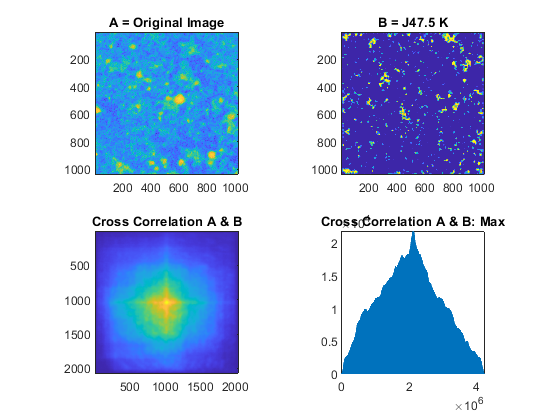

figure;

subplot(2, 2, 1)
imagesc(OG)
axis square
title('A = Original Image')

subplot(2, 2, 2)
imagesc(J47pt5)
axis square
title('B = J47.5 K')

subplot(2, 2, 3)
imagesc(c47pt5)
axis square
title('Cross Correlation A & B')

subplot(2, 2, 4)
plot(c47pt5(:))
axis square
title('Cross Correlation A & B: Max')

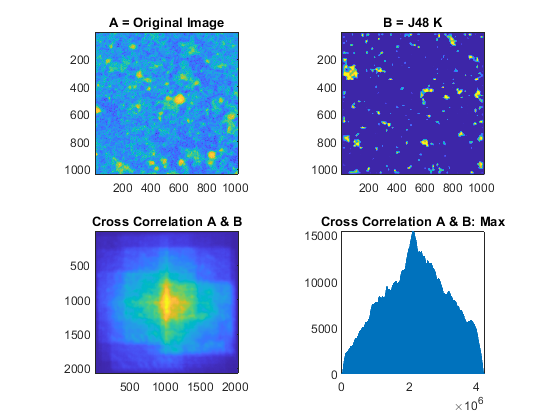

figure;
subplot(2, 2, 1)
imagesc(OG)
axis square
title('A = Original Image')

subplot(2, 2, 2)
imagesc(J48)
axis square
title('B = J48 K')

subplot(2, 2, 3)
imagesc(c48)
axis square
title('Cross Correlation A & B')

subplot(2, 2, 4)
plot(c48(:))
axis square
title('Cross Correlation A & B: Max')

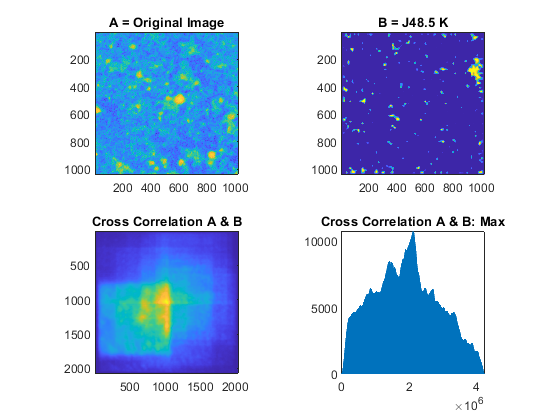

figure;

subplot(2, 2, 1)
imagesc(OG)
axis square
title('A = Original Image')

subplot(2, 2, 2)
imagesc(J48pt5)
axis square
title('B = J48.5 K')

subplot(2, 2, 3)
imagesc(c48pt5)
axis square
title('Cross Correlation A & B')

subplot(2, 2, 4)
plot(c48pt5(:))
axis square
title('Cross Correlation A & B: Max')

## Try with thresholded image

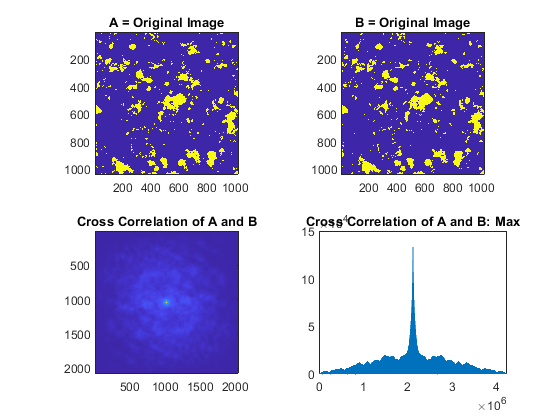

figure;
subplot(2, 2, 1)
imagesc(OGthcc)
title('A = Original Image')
axis square

subplot(2, 2, 2)
imagesc(OGthcc)
title('B = Original Image')
axis square

subplot(2, 2, 3)
imagesc(cselfth)
axis square
title('Cross Correlation of A and B')

subplot(2, 2, 4)
plot(cselfth(:))
title('Cross Correlation of A and B: Max')

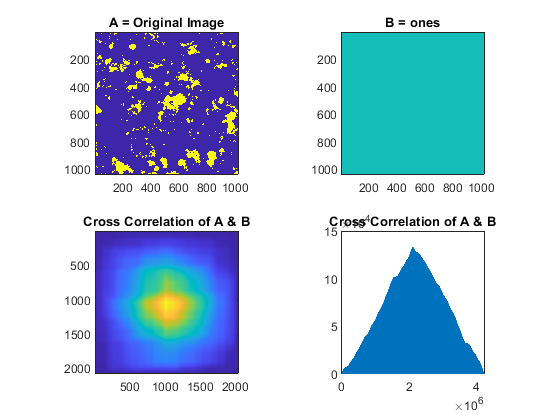

figure;
subplot(2, 2, 1)
imagesc(OGthcc)
title('A = Original Image')
axis square

subplot(2, 2, 2)
imagesc(onesImg)
title('B = ones')
axis square

subplot(2, 2, 3)
imagesc(conesth)
axis square
title('Cross Correlation of A & B')

subplot(2, 2, 4)
plot(conesth(:))
title('Cross Correlation of A & B')
axis square

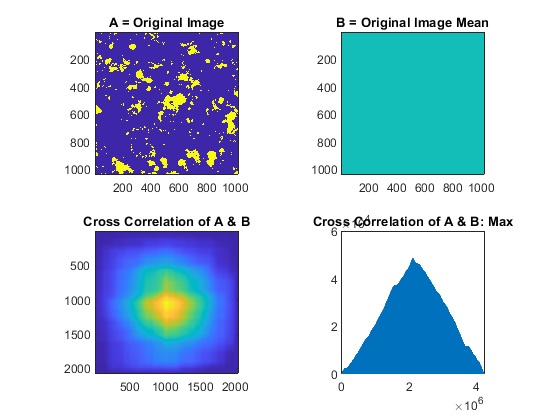

figure;
subplot(2, 2, 1)
imagesc(OGthcc)
title('A = Original Image')
axis square

subplot(2, 2, 2)
imagesc(meanOG)
title('B = Original Image Mean')
axis square

subplot(2, 2, 3)
imagesc(cmeanth)
axis square
title('Cross Correlation of A & B')

subplot(2, 2, 4)
plot(cmeanth(:))
axis square
title('Cross Correlation of A & B: Max')

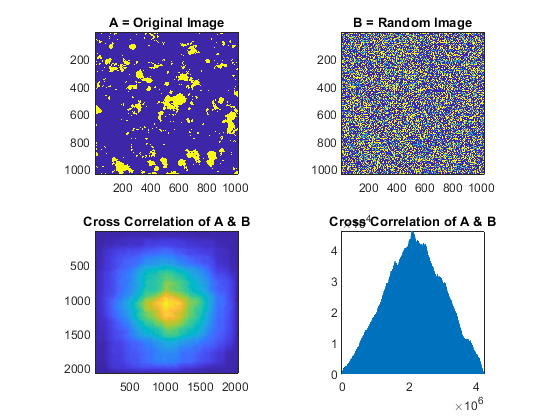

figure;

subplot(2, 2, 1)
imagesc(OGthcc)
axis square
title('A = Original Image')

subplot(2, 2, 2)
imagesc(randImg)
axis square
title('B = Random Image')

subplot(2, 2, 3)
imagesc(crandth)
axis square
title('Cross Correlation of A & B')


subplot(2, 2, 4)
plot(crandth(:))
axis square
title('Cross Correlation of A & B')

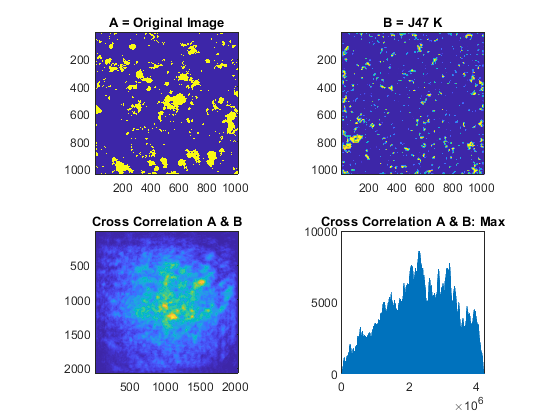

figure;

subplot(2, 2, 1)
imagesc(OGthcc)
axis square
title('A = Original Image')

subplot(2, 2, 2)
imagesc(J47cc)
axis square
title('B = J47 K')

subplot(2, 2, 3)
imagesc(c47th)
axis square
title('Cross Correlation A & B')

subplot(2, 2, 4)
plot(c47th(:))
axis square
title('Cross Correlation A & B: Max')

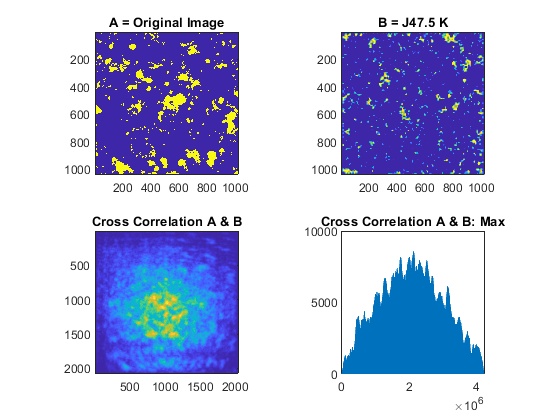

figure;

subplot(2, 2, 1)
imagesc(OGthcc)
axis square
title('A = Original Image')

subplot(2, 2, 2)
imagesc(J47pt5cc)
axis square
title('B = J47.5 K')

subplot(2, 2, 3)
imagesc(c47pt5th)
axis square
title('Cross Correlation A & B')

subplot(2, 2, 4)
plot(c47pt5th(:))
axis square
title('Cross Correlation A & B: Max')

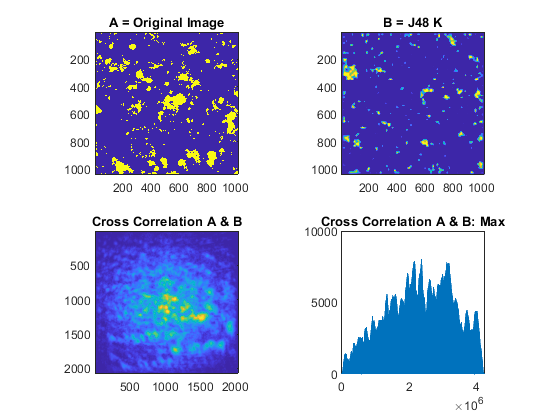

figure;
subplot(2, 2, 1)
imagesc(OGthcc)
axis square
title('A = Original Image')

subplot(2, 2, 2)
imagesc(J48cc)
axis square
title('B = J48 K')

subplot(2, 2, 3)
imagesc(c48th)
axis square
title('Cross Correlation A & B')

subplot(2, 2, 4)
plot(c48th(:))
axis square
title('Cross Correlation A & B: Max')

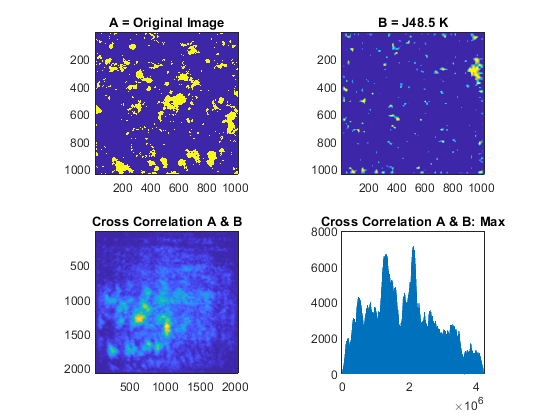

figure;

subplot(2, 2, 1)
imagesc(OGthcc)
axis square
title('A = Original Image')

subplot(2, 2, 2)
imagesc(J48pt5cc)
axis square
title('B = J48.5 K')

subplot(2, 2, 3)
imagesc(c48pt5th)
axis square
title('Cross Correlation A & B')

subplot(2, 2, 4)
plot(c48pt5th(:))
axis square
title('Cross Correlation A & B: Max')

## Do SSIM

r = 1.25;
[svalself, smapself] = ssim(OG, OG, 'radius', r);
svalself

svalself = 1

[svalzeros, smapzeros] = ssim(zerosImg, OG, 'radius', r);
svalzeros

svalzeros = 4.9384e-04

[svalones, smapones] = ssim(onesImg, OG, 'radius', r);
svalones

svalones = 0.3127

[svalmean, smapmean] = ssim(meanOG, OG, 'radius', r);
svalmean

svalmean = 0.4796

[svalrand, smaprand] = ssim(randImg, OG, 'radius', r);
svalrand

svalrand = 0.0146


[sval47, smap47] = ssim(J47, OG, 'radius', r);
sval47

sval47 = 0.0104

[sval47pt5, smap47pt5] = ssim(J47pt5, OG, 'radius', r);
sval47pt5

sval47pt5 = 0.0119

[sval48, smap48] = ssim(J48, OG, 'radius', r);
sval48

sval48 = 0.0122

[sval48pt5, smap48pt5] = ssim(J48pt5, OG, 'radius', r);
sval48pt5

sval48pt5 = 0.0106

## Thresholded SSIM

[svalselfth, smapselfth] = ssim(OG_threshold, OG_threshold, 'radius', r);
svalselfth

svalselfth = 1

[svalzerosth, smapzerosth] = ssim(zerosImg, OG_threshold, 'radius', r);
svalzerosth

svalzerosth = 0.7411

[svalonesth, smaponesth] = ssim(onesImg, OG_threshold, 'radius', r);
svalonesth

svalonesth = 0.0543

[svalmeanth, smapmeanth] = ssim(meanOG, OG_threshold, 'radius', r);
svalmeanth

svalmeanth = 0.0360

[svalrandth, smaprandth] = ssim(randImg, OG_threshold, 'radius', r);
svalrandth

svalrandth = 0.0757


[sval47th, smap47th] = ssim(J47, OG_threshold, 'radius', r);
sval47th

sval47th = 0.6048

[sval47pt5th, smap47pt5th] = ssim(J47pt5, OG_threshold, 'radius', r);
sval47pt5th

sval47pt5th = 0.6089

[sval48th, smap48th] = ssim(J48, OG_threshold, 'radius', r);
sval48th

sval48th = 0.6409

[sval48pt5th, smap48pt5th] = ssim(J48pt5, OG_threshold, 'radius', r);
sval48pt5th

sval48pt5th = 0.6619

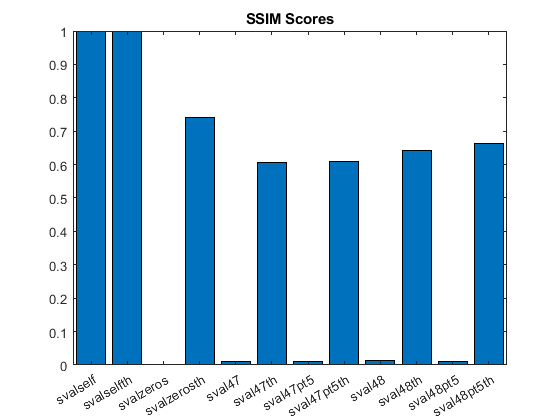

ssim_names = categorical({'svalself', 'svalselfth', 'svalzeros', 'svalzerosth', 'sval47', 'sval47th', ...
    'sval47pt5', 'sval47pt5th', 'sval48', 'sval48th', 'sval48pt5', 'sval48pt5th'});

ssim_names = reordercats(ssim_names,{'svalself', 'svalselfth', 'svalzeros', 'svalzerosth','sval47', 'sval47th', ...
    'sval47pt5', 'sval47pt5th', 'sval48', 'sval48th', 'sval48pt5', 'sval48pt5th'});

ssim_values = [svalself, svalselfth, svalzeros, svalzerosth, sval47, sval47th, ...
    sval47pt5, sval47pt5th, sval48, sval48th, sval48pt5, sval48pt5th];

figure;
bar(ssim_names, ssim_values);
%ylim([0.984 1])
title('SSIM Scores')

## Show SSIM

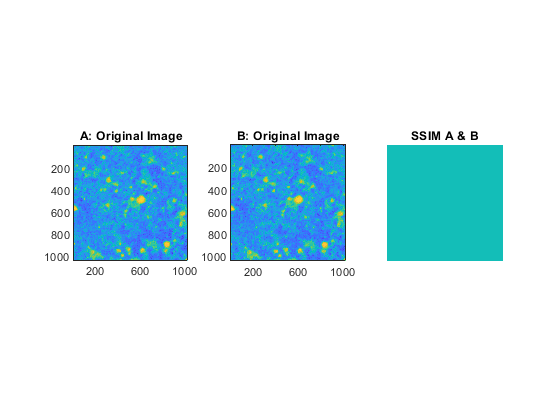

figure;
subplot(1, 3, 1)
imagesc(OG)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(OG)
axis square
title('B: Original Image')

subplot(1, 3, 3)
imagesc(smapself)
axis square
title('SSIM A & B')
axis off

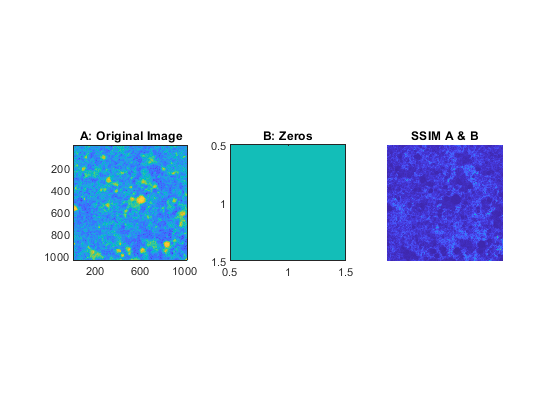

figure;
subplot(1, 3, 1)
imagesc(OG)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(zeros)
axis square
title('B: Zeros')

subplot(1, 3, 3)
imagesc(smapzeros)
axis square
title('SSIM A & B')
axis off

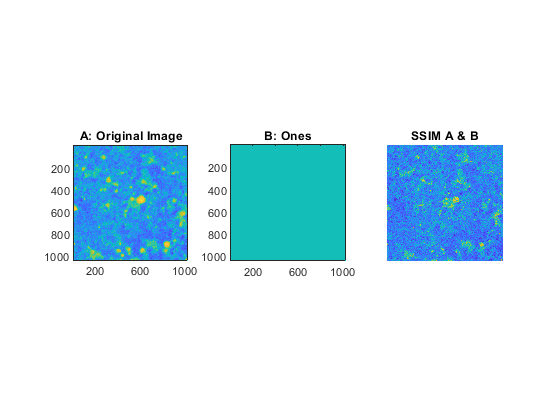

figure;
subplot(1, 3, 1)
imagesc(OG)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(onesImg)
axis square
title('B: Ones')

subplot(1, 3, 3)
imagesc(smapones)
axis square
title('SSIM A & B')
axis off

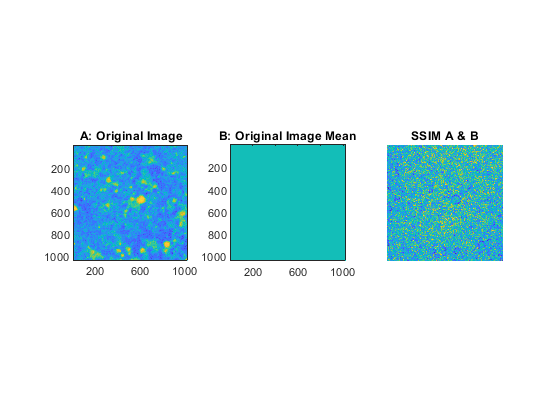


figure;
subplot(1, 3, 1)
imagesc(OG)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(meanOG)
axis square
title('B: Original Image Mean')

subplot(1, 3, 3)
imagesc(smapmean)
axis square
axis off
title('SSIM A & B')

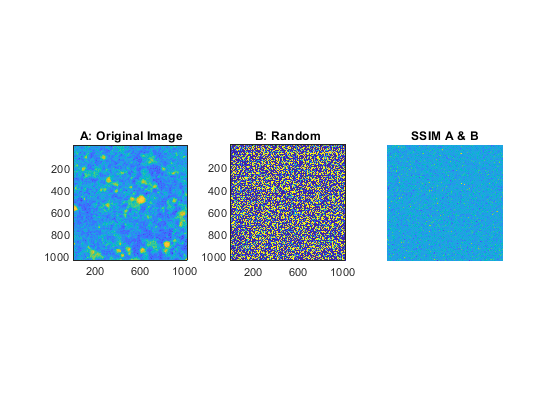

figure;
subplot(1, 3, 1)
imagesc(OG)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(randImg)
axis square
title('B: Random')

subplot(1, 3, 3)
imagesc(smaprand)
axis square
axis off
title('SSIM A & B')

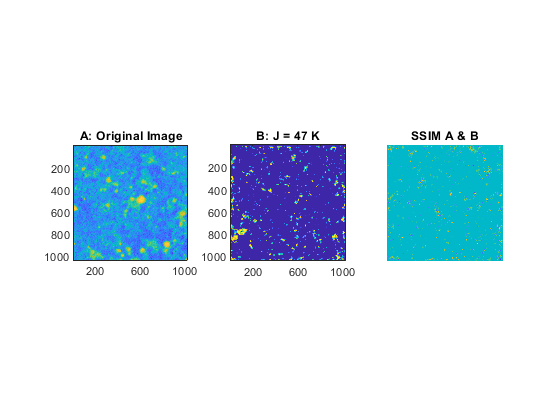

figure;
subplot(1, 3, 1)
imagesc(OG)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(J47)
axis square
title('B: J = 47 K')

subplot(1, 3, 3)
imagesc(smap47pt5)
title('SSIM A & B')
axis square
axis off

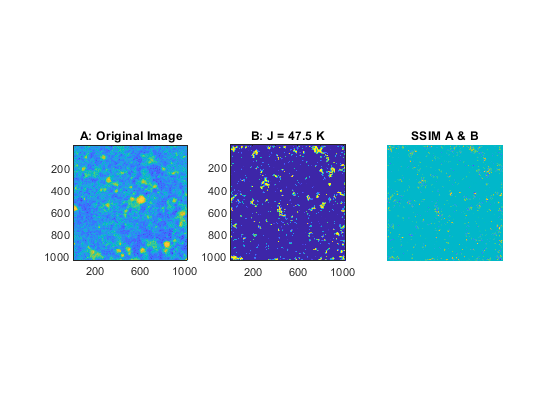


figure;
subplot(1, 3, 1)
imagesc(OG)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(J47pt5)
axis square
title('B: J = 47.5 K')

subplot(1, 3, 3)
imagesc(smap47pt5)
title('SSIM A & B')
axis square
axis off

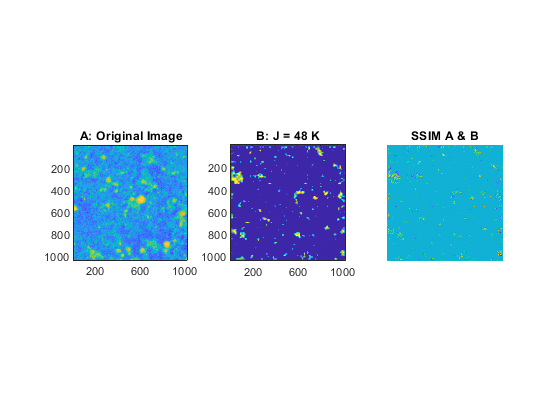

figure;
subplot(1, 3, 1)
imagesc(OG)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(J48)
axis square
title('B: J = 48 K')

subplot(1, 3, 3)
imagesc(smap48)
title('SSIM A & B')
axis square
axis off

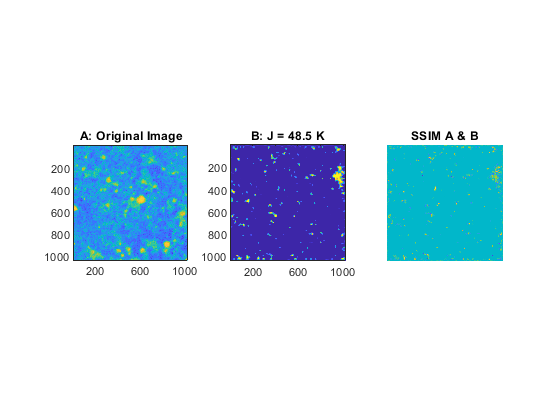

figure;
subplot(1, 3, 1)
imagesc(OG)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(J48pt5)
axis square
title('B: J = 48.5 K')

subplot(1, 3, 3)
imagesc(smap48pt5)
title('SSIM A & B')
axis square
axis off

## SSIM Thresholded Imgs

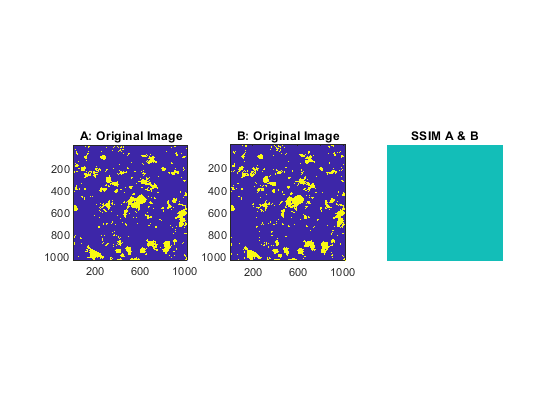

figure;
subplot(1, 3, 1)
imagesc(OG_threshold)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(OG_threshold)
axis square
title('B: Original Image')

subplot(1, 3, 3)
imagesc(smapselfth)
axis square
title('SSIM A & B')
axis off

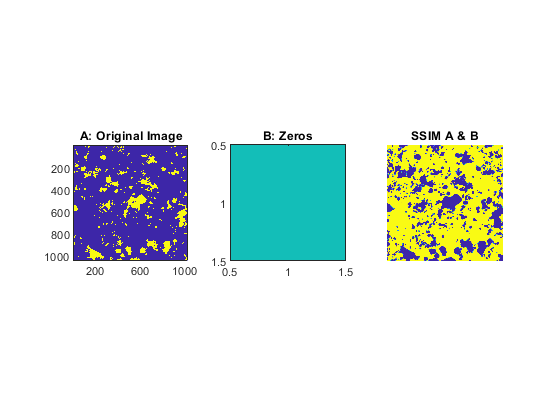

figure;
subplot(1, 3, 1)
imagesc(OG_threshold)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(zeros)
axis square
title('B: Zeros')

subplot(1, 3, 3)
imagesc(smapzerosth)
axis square
title('SSIM A & B')
axis off

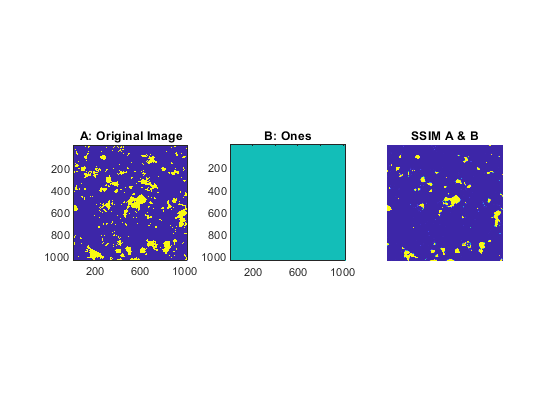

figure;
subplot(1, 3, 1)
imagesc(OG_threshold)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(onesImg)
axis square
title('B: Ones')

subplot(1, 3, 3)
imagesc(smaponesth)
axis square
title('SSIM A & B')
axis off

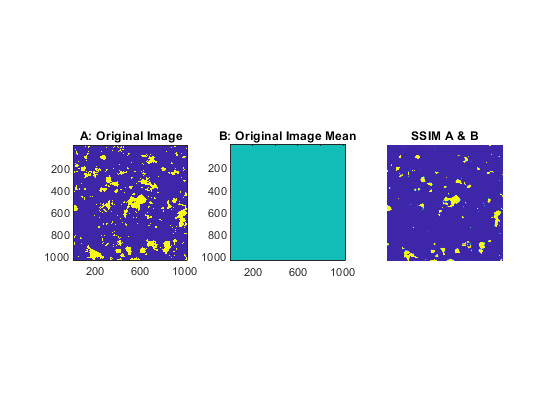

figure;
subplot(1, 3, 1)
imagesc(OG_threshold)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(meanOG)
axis square
title('B: Original Image Mean')

subplot(1, 3, 3)
imagesc(smapmeanth)
axis square
axis off
title('SSIM A & B')

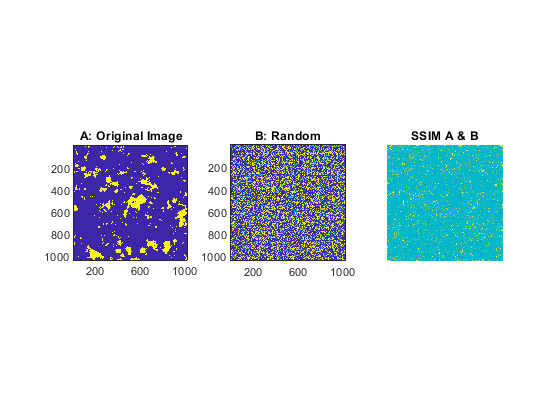

figure;
subplot(1, 3, 1)
imagesc(OG_threshold)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(randImg)
axis square
title('B: Random')

subplot(1, 3, 3)
imagesc(smaprandth)
axis square
axis off
title('SSIM A & B')

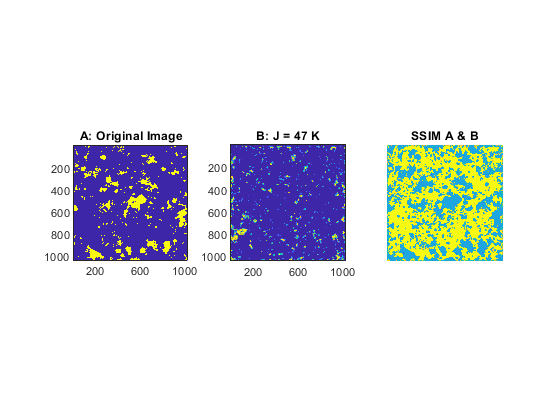

figure;
subplot(1, 3, 1)
imagesc(OG_threshold)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(J47)
axis square
title('B: J = 47 K')

subplot(1, 3, 3)
imagesc(smap47pt5th)
title('SSIM A & B')
axis square
axis off

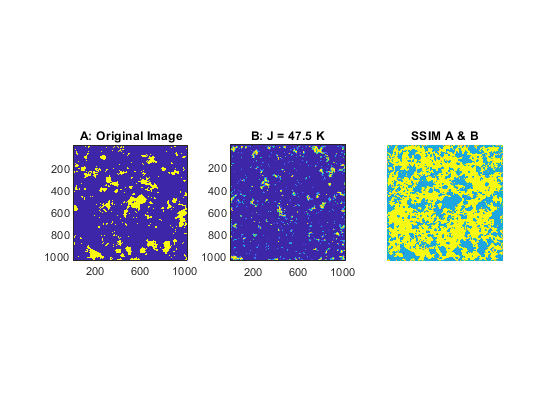


figure;
subplot(1, 3, 1)
imagesc(OG_threshold)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(J47pt5)
axis square
title('B: J = 47.5 K')

subplot(1, 3, 3)
imagesc(smap47pt5th)
title('SSIM A & B')
axis square
axis off

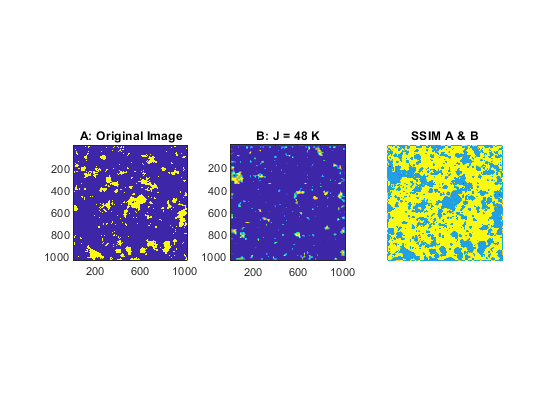

figure;
subplot(1, 3, 1)
imagesc(OG_threshold)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(J48)
axis square
title('B: J = 48 K')

subplot(1, 3, 3)
imagesc(smap48th)
title('SSIM A & B')
axis square
axis off

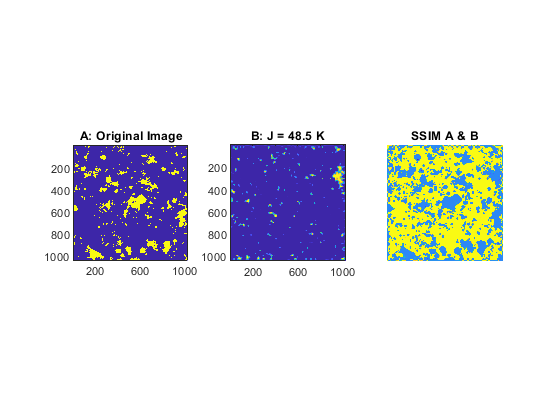

figure;
subplot(1, 3, 1)
imagesc(OG_threshold)
axis square
title('A: Original Image')

subplot(1, 3, 2)
imagesc(J48pt5)
axis square
title('B: J = 48.5 K')

subplot(1, 3, 3)
imagesc(smap48pt5th)
title('SSIM A & B')
axis square
axis off

## Do Multi Scale SSIM

% [msvalself, msmapself] = multissim(OG, OG);
% msvalself
% [msvalzeros, msmapzeros] = multissim(zerosImg, OG);
% msvalzeros
% [msvalones, msmapones] = multissim(onesImg, OG);
% msvalones
% [msvalmean, msmapmean] = multissim(meanOG, OG);
% msvalmean
% [msvalrand, msmaprand] = multissim(randImg, OG);
% msvalrand
% 
% [msval47, msmap47] = ssim(J47, OG);
% msval47
% [msval47pt5, msmap47pt5] = ssim(J47pt5, OG);
% msval47pt5
% [msval48, msmap48] = ssim(J48, OG);
% msval48
% [msval48pt5, msmap48pt5] = ssim(J48pt5, OG);
% msval48pt5

## Show Multi Scale SSIM

% figure;
% subplot(1, 3, 1)
% imagesc(OG)
% axis square
% title('A: Original Image')
% 
% subplot(1, 3, 2)
% imagesc(OG)
% axis square
% title('B: Original Image')
% 
% subplot(1, 3, 3)
% imagesc(msmapself{1,1})
% axis square
% title('SSIM A & B')
% axis off

% figure;
% subplot(1, 3, 1)
% imagesc(OG)
% axis square
% title('A: Original Image')
% 
% subplot(1, 3, 2)
% imagesc(zeros)
% axis square
% title('B: Zeros')
% 
% subplot(1, 3, 3)
% imagesc(msmapzeros{1,1})
% axis square
% title('SSIM A & B')
% axis off

% figure;
% subplot(1, 3, 1)
% imagesc(OG)
% axis square
% title('A: Original Image')
% 
% subplot(1, 3, 2)
% imagesc(onesImg)
% axis square
% title('B: Ones')
% 
% subplot(1, 3, 3)
% imagesc(msmapones{1,1})
% axis square
% title('SSIM A & B')
% axis off

% figure;
% subplot(1, 3, 1)
% imagesc(OG)
% axis square
% title('A: Original Image')
% 
% subplot(1, 3, 2)
% imagesc(meanOG)
% axis square
% title('B: Original Image Mean')
% 
% subplot(1, 3, 3)
% imagesc(msmapmean{1,1})
% axis square
% axis off
% title('SSIM A & B')

% figure;
% subplot(1, 3, 1)
% imagesc(OG)
% axis square
% title('A: Original Image')
% 
% subplot(1, 3, 2)
% imagesc(randImg)
% axis square
% title('B: Random')
% 
% subplot(1, 3, 3)
% imagesc(msmaprand{1,1})
% axis square
% axis off
% title('SSIM A & B')

% figure;
% subplot(1, 3, 1)
% imagesc(OG)
% axis square
% title('A: Original Image')
% 
% subplot(1, 3, 2)
% imagesc(J47)
% axis square
% title('B: J = 47 K')
% 
% subplot(1, 3, 3)
% imagesc(msmap47)
% title('SSIM A & B')
% axis square
% axis off

% 
% figure;
% subplot(1, 3, 1)
% imagesc(OG)
% axis square
% title('A: Original Image')
% 
% subplot(1, 3, 2)
% imagesc(J47pt5)
% axis square
% title('B: J = 47.5 K')
% 
% subplot(1, 3, 3)
% imagesc(msmap47pt5)
% title('SSIM A & B')
% axis square
% axis off

% figure;
% subplot(1, 3, 1)
% imagesc(OG)
% axis square
% title('A: Original Image')
% 
% subplot(1, 3, 2)
% imagesc(J48)
% axis square
% title('B: J = 48 K')
% 
% subplot(1, 3, 3)
% imagesc(msmap48)
% title('SSIM A & B')
% axis square
% axis off

% figure;
% subplot(1, 3, 1)
% imagesc(OG)
% axis square
% title('A: Original Image')
% 
% subplot(1, 3, 2)
% imagesc(J48pt5)
% axis square
% title('B: J = 48.5 K')
% 
% subplot(1, 3, 3)
% imagesc(msmap48pt5)
% title('SSIM A & B')
% axis square
% axis off